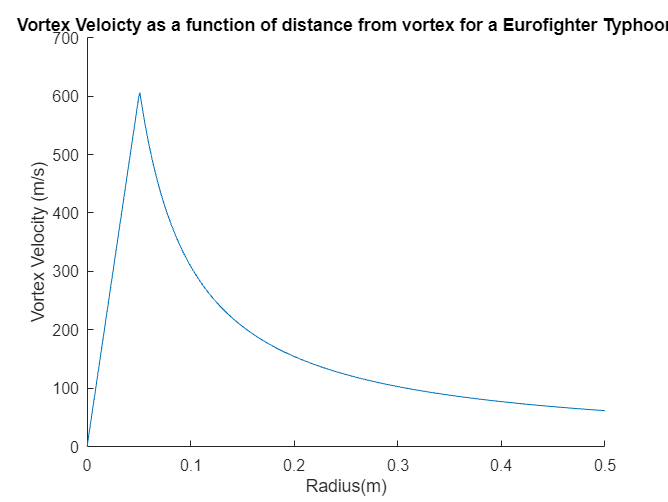

investigateVortexVelocity

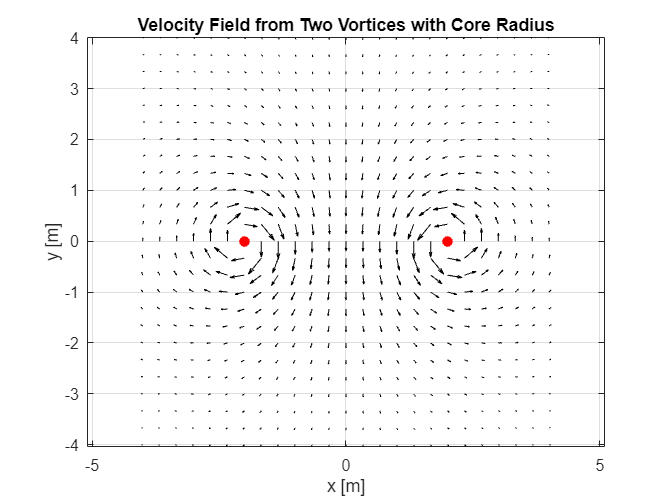

% === Parameters ===
mass = 1000;                 % kg
load_factor = 1.5;           % dimensionless
g = 9.81;                    % m/s^2
rho = 1.225;                 % kg/m^3
a = 10;                      % m (wingspan)
V_airplane = 50;             % m/s
rcore = 0.5;                 % vortex core radius [m]

% Lift and circulation
L = load_factor * mass * g;
Gamma = L / (rho * a * V_airplane);  % Circulation [m^2/s]

% Two vortex positions and circulations
xj = [-2, 2];
yj = [0, 0];
Gamma_j = [-Gamma, Gamma]; % One clockwise, one counter-clockwise
N = 2; %Number of 

% === Grid ===
[x, y] = meshgrid(linspace(-4, 4, 25), linspace(-4, 4, 25));
u = zeros(size(x));
v = zeros(size(y));

% === Velocity field calculation ===
for j = 1:N
    dx = x - xj(j);
    dy = y - yj(j);
    r2 = dx.^2 + dy.^2;
    r = sqrt(r2);

    % Avoid division by zero
    r(r==0) = eps;

    % Tangential velocity components
    outside_core = r > rcore;
    inside_core = ~outside_core;

    % Outside core
    u(outside_core) = u(outside_core) + ...
        -Gamma_j(j) ./ (2 * pi * r2(outside_core)) .* dy(outside_core);
    v(outside_core) = v(outside_core) + ...
         Gamma_j(j) ./ (2 * pi * r2(outside_core)) .* dx(outside_core);

    % Inside core
    u(inside_core) = u(inside_core) + ...
        -Gamma_j(j) ./ (2 * pi * rcore^2) .* dy(inside_core);
    v(inside_core) = v(inside_core) + ...
         Gamma_j(j) ./ (2 * pi * rcore^2) .* dx(inside_core);
end

% === Plot ===
figure;
quiver(x, y, u, v, 'k')
hold on;
plot(xj, yj, 'ro', 'MarkerFaceColor', 'r')
xlabel('x [m]'); ylabel('y [m]');
title('Velocity Field from Two Vortices with Core Radius');
axis equal;
grid on;

function investigateVortexVelocity
%For a Eurofighter Typhoon flying at 10000ft and 250m/s
radiusValues=[];
radius=0;
velocityVortex=[];
massTyphoon = 15000;
mass=massTyphoon;
loadFactor=1.5;
g=9.81;
densityOfAir=0.4135;
Wingspan = 11;
aircraftVelocity = 250;
velcoityVortexCore = 600;
radiusCore=0.05;
for radius = 0:0.001:0.05
    velocityVortexCurrent = (velcoityVortexCore/radiusCore)*radius;
    radiusValues=[radiusValues,radius];
    velocityVortex=[velocityVortex,velocityVortexCurrent];
end
for radius = 0.051:0.001:0.5
    velocityVortexCurrent = (loadFactor*mass*g)/(densityOfAir*Wingspan*aircraftVelocity*2*pi*radius);
    radiusValues=[radiusValues,radius];
    velocityVortex=[velocityVortex,velocityVortexCurrent];
end
radiusValues;
velocityVortex;
figure;
hold on;
plot(radiusValues,velocityVortex)
xlabel('Radius(m)');
ylabel('Vortex Velocity (m/s)');
title('Vortex Veloicty as a function of distance from vortex for a Eurofighter Typhoon')
hold off;
end
